# Assignment 2. Forward and Inverse Problems

## **Murong Xu **

Here is your second assignment for the course which consists of 2 tasks. Some guidlines what is expected from you:

- It would be nice if you present your solutions using the Live Script form.

- Please, make sure that your code actually runs! Clear Workspace and run each line of code to be sure.** If I am not able to run the code from the 1st attempt, the assignment does not count for the exam bonus. 					**

- Every figure should have a number and a title. In the text refer to figures by their number. Every plot should have titled axes. If the figure consists of several subplots, each one should have a self-explanatory title. 	

- Comments to the code are highly appreciated.

- Try to make your answers brief, usually 1-2 sectence are enough to answer the question.					

- Please, send me your solutions using the email anna.tenditnaya@tum.de until 5.01.2022 23:59. 

- **All assignments submitted after the deadline do not count for the exam bonus.**

For task 1 and 2 it is recommended to refer to the materials from the lecture about forward problems in imaging as well as to the Tutorial 3.

## Task 1. Finite Difference Method

**T1.1**: Come up with a simple one dimensional differential equation $f^{\prime } \left(x\right)=g\left(x\right)$on $\Omega =\left\lbrack 0,1\right\rbrack$ by specifying $g\left(x\right)$ and setting appropriate boundary condition (e. g. $f\left(0\right)=0$).

*Define the problem setting: *$f^{\prime } \left(x\right)=5x+2$* on *$\Omega =\left\lbrack 0,1\right\rbrack$* with boundary condition *$f\left(0\right)=1$*.*

**T1.2**: Solve the obtained boundary value problem analytically. Show your solution as well as its plot. 

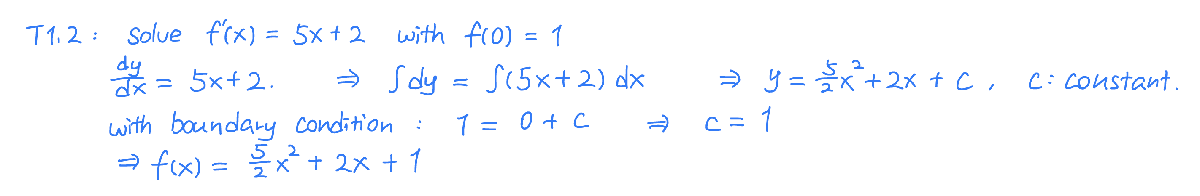

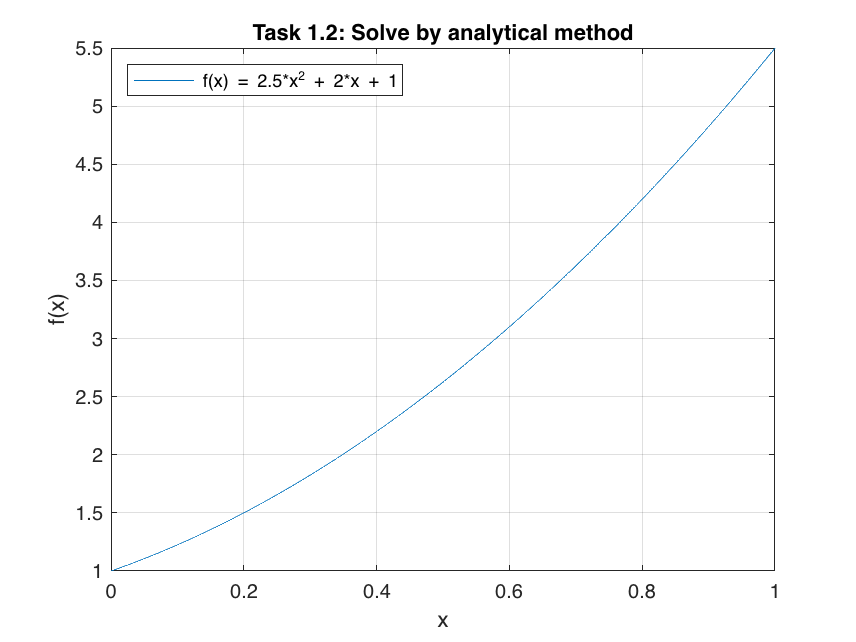

% Show the solution as plot 
x_analytical = linspace(0,1,1000);
f_analytical = 2.5 * (x_analytical).^2 + 2 * x_analytical + 1;
figure(1); 
plot(x_analytical, f_analytical, 'DisplayName', 'f(x) = 2.5*x^2 + 2*x + 1'); 
hold on
xlabel('x');
ylabel('f(x)');
title('Task 1.2: Solve by analytical method');
grid on
hold off
legend('Location', 'northwest')

**T1.3**: Solve the boundary value problem using the Finite Difference Method for step h = 0.2, 0.1 and 0.01. Pick the discretization scheme yourself (forward/backward/central difference), discretize the equation and put it into matrix form. Use linsolve() to solve the resulting system of linear equations. *Hint:* unless you know what you are doing, avoid the central difference scheme. 

h = [0.2, 0.1, 0.01]; % steps
num_step_size = length(h);
A_FDM = cell(num_step_size, 1);
b_FDM = cell(num_step_size, 1);
x_FDM = cell(num_step_size, 1);
f_FDM = cell(num_step_size, 1);
for i=1:num_step_size
    step_size = h(i);
    x_temp = 0:step_size:1; % coordinates of the grid
    % initilization 
    A_temp = zeros(numel(x_temp));
    b_temp = zeros(size(A_temp, 2), 1);
    % boundary condition
    A_temp(1,1) = 1; 
    b_temp(1) = 1;
    for k=2:numel(x_temp)
        % use forward difference method
        A_temp(k, k) = 1;
        A_temp(k, k-1) = -1;        
        b_temp(k) = step_size * (5 * x_temp(k) + 2);
    end
    % store in cell array
    A_FDM{i} = A_temp;
    b_FDM{i} = b_temp;
    x_FDM{i} = x_temp;
    % solve equation
    f_FDM{i} = linsolve(A_FDM{i}, b_FDM{i}); 
end

**T1.4**: Plot the resulting solutions along with the exact solution you have computed in step 2. 

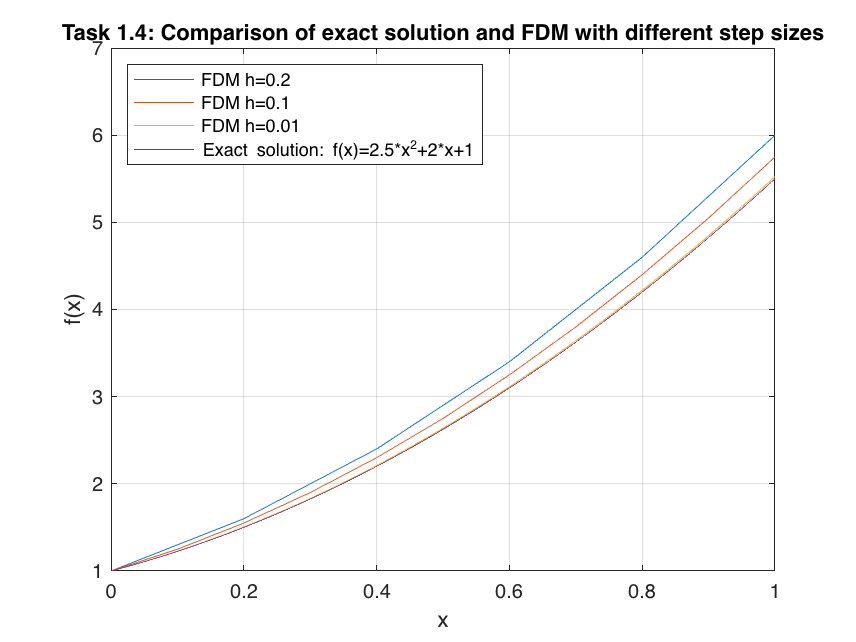

figure(2); 
plot(x_FDM{1}, f_FDM{1}, 'DisplayName','FDM h=0.2'); 
hold on
plot(x_FDM{2}, f_FDM{2}, 'DisplayName','FDM h=0.1'); 
hold on
plot(x_FDM{3}, f_FDM{3}, 'DisplayName','FDM h=0.01'); 
hold on
plot(x_analytical, f_analytical, 'DisplayName','Exact solution: f(x)=2.5*x^2+2*x+1'); 
hold on
xlabel('x');
ylabel('f(x)');
title('Task 1.4: Comparison of exact solution and FDM with different step sizes');
grid on
hold off
legend('Location', 'northwest')

## Task 2. Finite Element Method

**T2.1**: Derive quadratic interpolation functions for the finite element method. Plot them in local coordinates. Show your derivation. 

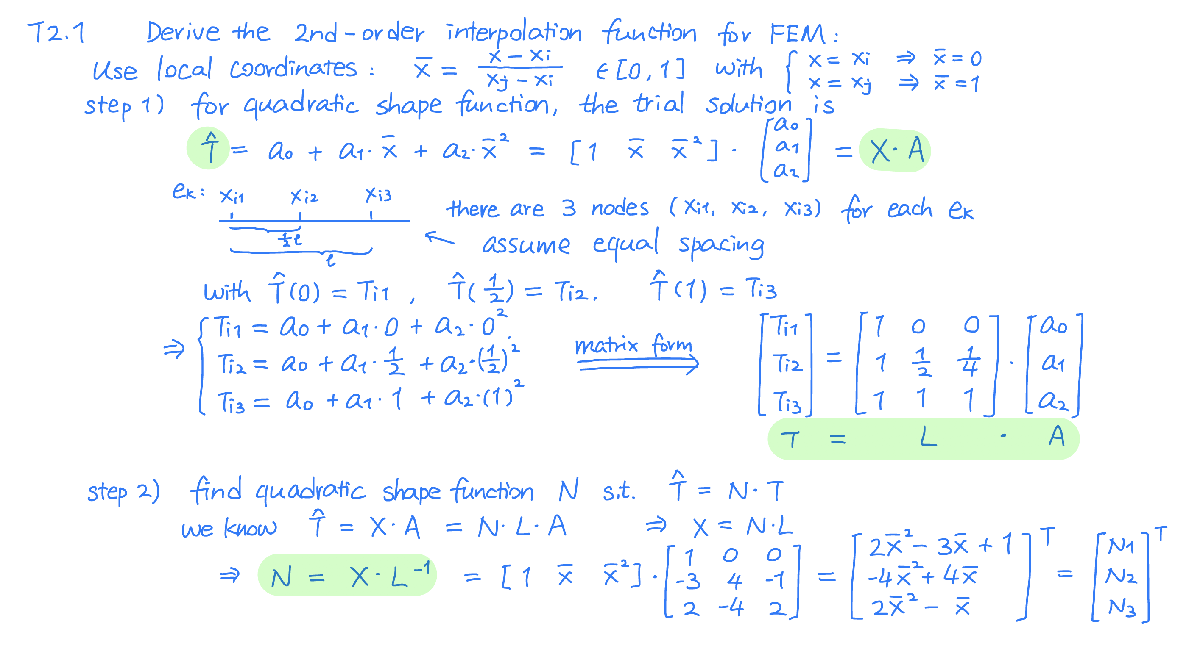

L = sym([1, 0, 0; 1, 0.5, 0.25; 1, 1, 1]) % matrix in local coordinates

$$L = \left(\begin{array}{ccc} 1 & 0 & 0\\ 1 & \frac{1}{2} & \frac{1}{4}\\ 1 & 1 & 1 \end{array}\right)$$

disp('Inverse of L:')

Inverse of L:


inv(L) 

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ -3 & 4 & -1\\ 2 & -4 & 2 \end{array}\right)$$


syms x
X = sym([1, x, x.^2]); % local coordinates
N = sym(X * inv(L));
N1 = N(1,1) 

$$N1 = 2\,x^{2}-3\,x+1$$

N2 = N(1,2)  

$$N2 = 4\,x-4\,x^{2}$$

N3 = N(1,3)    

$$N3 = 2\,x^{2}-x$$

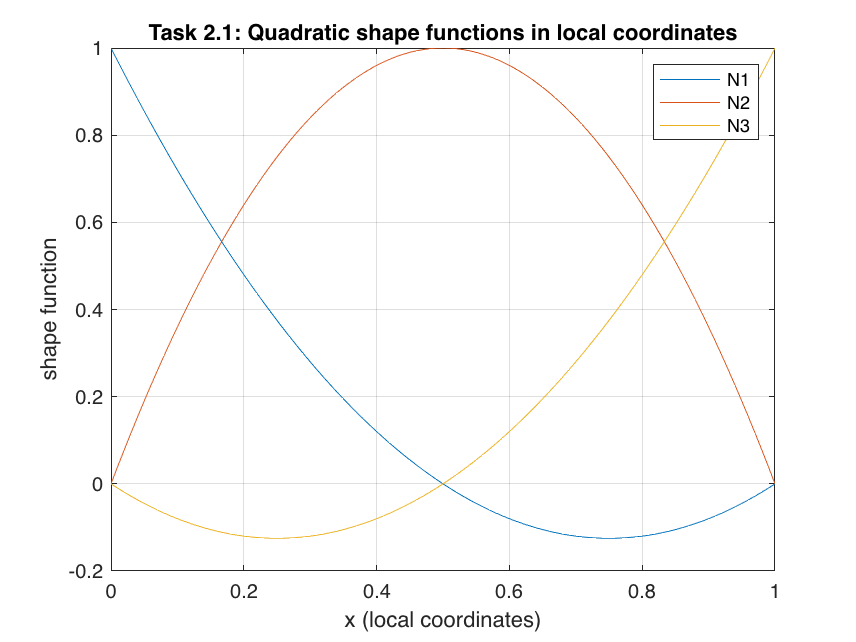


% visualize quadratic shape functions in local coordinates
x = 0:0.01:1; 
figure(3); 
plot(x, subs(N1), 'DisplayName', 'N1'); hold on;
plot(x, subs(N2), 'DisplayName', 'N2'); hold on;
plot(x, subs(N3), 'DisplayName', 'N3'); hold on;
xlabel('x (local coordinates)');
ylabel('shape function');
title('Task 2.1: Quadratic shape functions in local coordinates');
grid on
hold off
legend('Location', 'northeast')

**T2.2**: Consider a 1D steady state heat conduction problem: $k\textrm{T"}+S=0$ on $\Omega =\left\lbrack 0,1\right\rbrack$ with b.c. $T^{\prime } \left(0\right)=0,T\left(1\right)=0$, where k and S are constant. How would the stiffness matrix for one element look like for the shape functions derived in step 1?

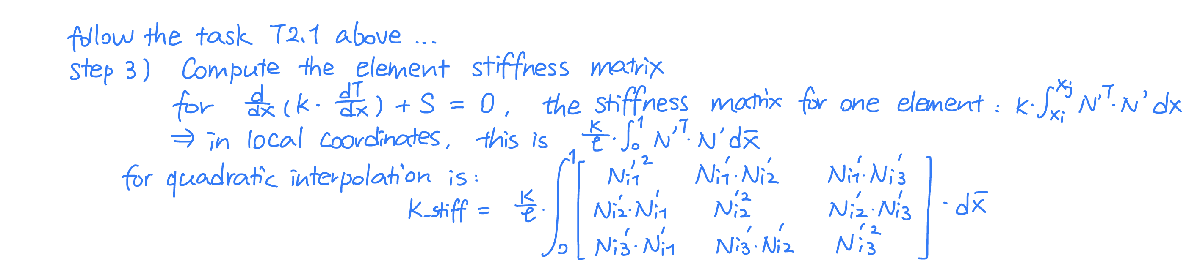

% assemble stiffness matrix for one element
syms x

k11 = int( diff(N1, x)*diff(N1, x), x, 0, 1 );
k22 = int( diff(N2, x)*diff(N2, x), x, 0, 1 );
k33 = int( diff(N3, x)*diff(N3, x), x, 0, 1 );

k12 = int( diff(N1, x)*diff(N2, x), x, 0, 1 ); k21 = k12;
k13 = int( diff(N1, x)*diff(N3, x), x, 0, 1 ); k31 = k13;
k23 = int( diff(N2, x)*diff(N3, x), x, 0, 1 ); k32 = k23;

K_stiff = [k11, k12, k13; k21, k22, k23; k31, k32, k33];
disp('stiffness matrix K (for one element):')

stiffness matrix K (for one element):


double(K_stiff)

ans =     2.3333   -2.6667    0.3333
   -2.6667    5.3333   -2.6667
    0.3333   -2.6667    2.3333


*Then, solve the 1D steady state head conduction problem. Use two methods: direct solution and FEM solution.*

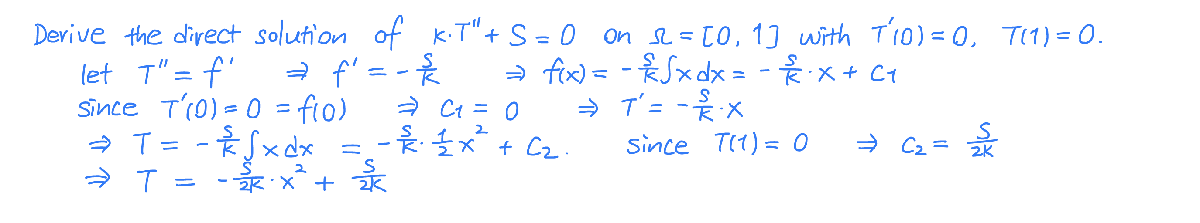

% assemble global stiffnes matrix and load vector 
nodes = 3; % for quadratic shape functions
Ke = double(K_stiff);
RHSe = int([N1, N2, N3], x, 0, 1)';

% define the problem setting
T1 = 0; % boundary condition
NumEl = 3; % number of elements
L = 1; % domain length
k = 1; % thermal conductivity
S = 100; % source
l = L/NumEl; % node spacing assuming equidistant nodes
dim = NumEl*(nodes - 1) +1; % dimension of stiffness matrix

K = zeros(dim); % initialize stiffness matrix with zeros
RHS = zeros([dim, 1]); % initialize load vector with zeros

% loop for all elements
for i = 1:NumEl 
    % compute indices of entries for a given element
    ind_start = 1+(i-1)*(nodes-1); 
    ind_end = ind_start + (nodes-1);
    % update stiffness matrix with the stiffness matrix of a single element
    K(ind_start:ind_end, ind_start:ind_end) = K(ind_start:ind_end, ind_start:ind_end) + Ke;
    % update load vector
    RHS(ind_start:ind_end) = RHS(ind_start:ind_end)+RHSe;
end

K = (k/l)*K; % multiply by constants
F = S*l*RHS;

large_number = 1e10; % a trick not to exclude T(1)=0
K(end,end) = K(end,end) + large_number;
F(end) = large_number * T1;

T_FEM = linsolve(K, F) % solve for T

T_FEM =    50.0000
   48.6111
   44.4444
   37.5000
   27.7778
   15.2778
    0.0000


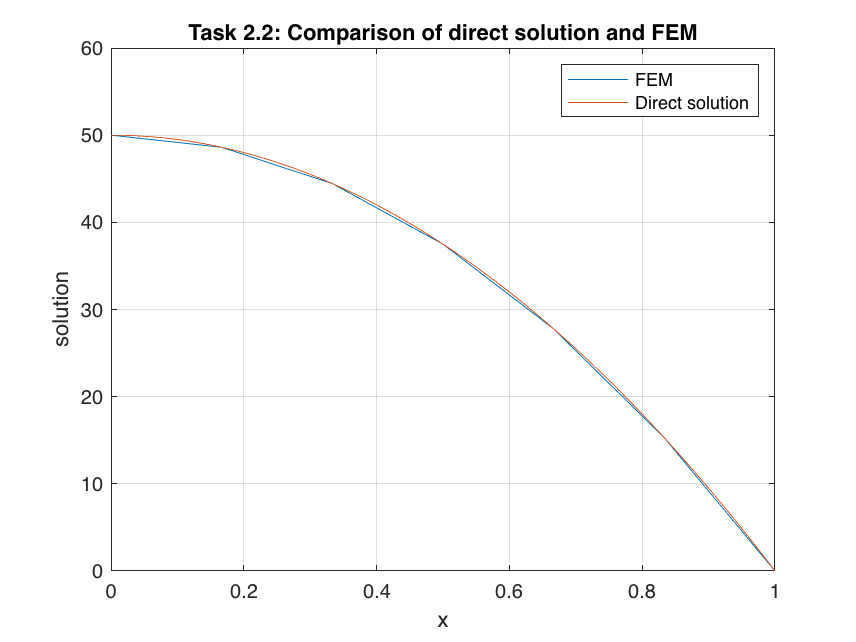


% plot and compare direct solution and FEM
x_FEM = 0:l/(nodes-1):1; 
x_direct = 0:0.01:1; 
solution = -S/(2*k)*x_direct.^2 + S/(2*k); % direct solution
figure(4);
plot(x_FEM, T_FEM, 'DisplayName', 'FEM'); 
hold on 
plot(x_direct, solution, 'DisplayName', 'Direct solution'); 
xlabel('x');
ylabel('solution');
title('Task 2.2: Comparison of direct solution and FEM');
grid on
hold off
legend('Location', 'northeast')


% compute the FEM error
error_FEM = T_FEM - (-S/(2*k)*x_FEM.^2 + S/(2*k))'; 
disp('Norm of FEM error (compared to direct solution):')

Norm of FEM error (compared to direct solution):


norm(error_FEM)

ans = 2.4988e-08

For the next tasks you will need to use the materials from the lecture about inverse problems and Tutorial 4 on the same topic.

## Task 3. An Imaging Problem

Let's take a problem which were discussed in the Tutorial 4 (see Example: Simple Inversion):

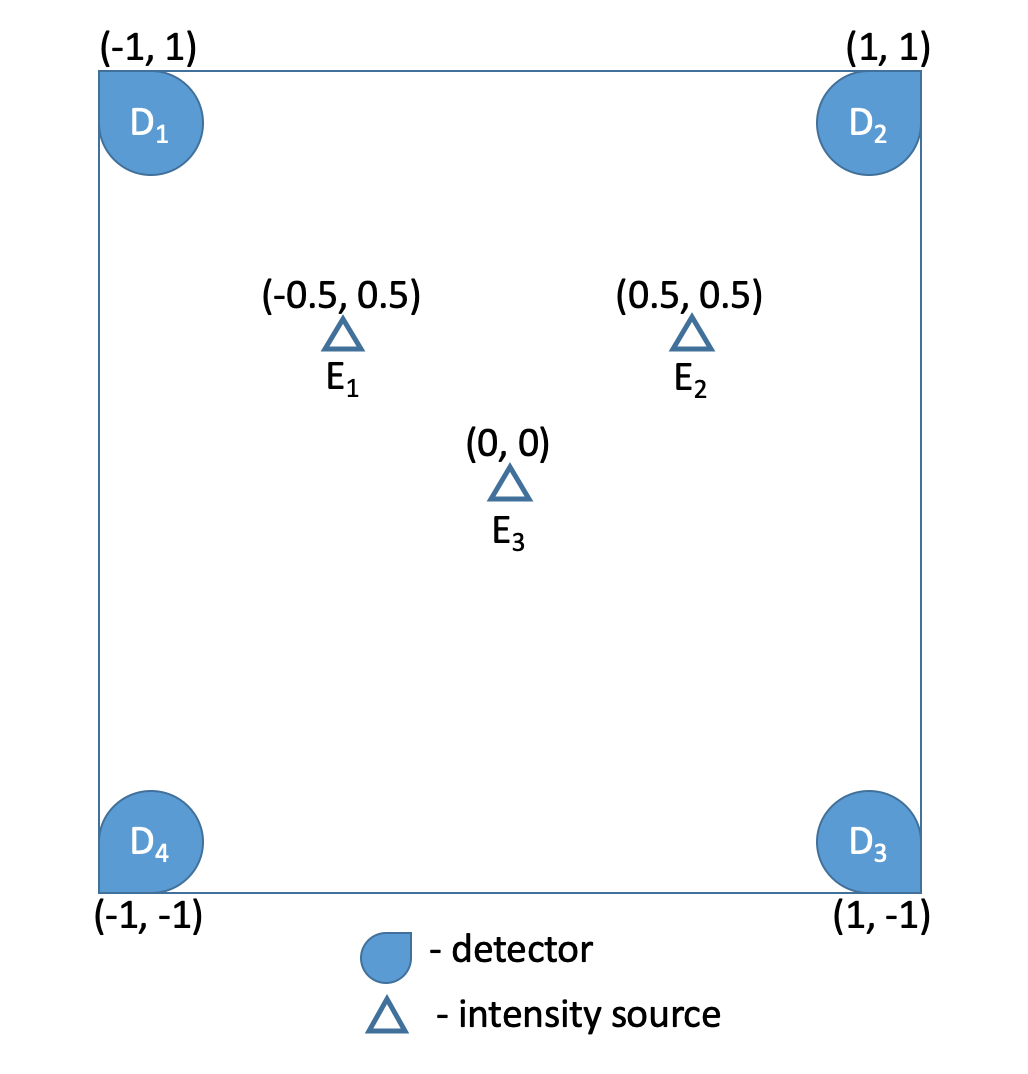

**T3.1**: Add 2 other sources $E_4$ and $E_5$ close to $E_3$. You can use the matlab code: 															

% distance matrix of sources E1, E2, E3
r= [sqrt(2)/2, sqrt(10)/2, sqrt(18)/2, sqrt(10)/2;
    sqrt(10)/2, sqrt(2)/2, sqrt(10)/2, sqrt(18)/2;
    sqrt(2), sqrt(2), sqrt(2), sqrt(2)]; % r(i,j) distance from  Ei to Dj
r4 = [sqrt(1+0.99^2), sqrt(1+0.99^2), sqrt(1+1.01^2), sqrt(1+1.01^2)]; % add E4 light source 								
r5 = [sqrt(1+0.99^2), sqrt(1+1.01^2), sqrt(1+1.01^2), sqrt(1+0.99^2)]; % add E5 light source 	
r=[r; r4; r5];

% create system matrix
disp('System matrix:')

System matrix:


A=(r.').^(-2) 

A =     2.0000    0.4000    0.5000    0.5050    0.5050
    0.4000    2.0000    0.5000    0.5050    0.4950
    0.2222    0.4000    0.5000    0.4950    0.4950
    0.4000    0.2222    0.5000    0.4950    0.5050


**T3.2**: Calculate the solution of the inverse problem with and without adding noise. Assume source values of [$I_{e,1}$,$I_{e,2}$,$\left.I_{e,3} ,I_{e,4} ,I_{e,5} ,\right\rbrack =\left\lbrack 4,3,1,1,1\right\rbrack$ for computing the measured data;

disp('Measurements:')

Measurements:


d = A * [4; 3; 1; 1; 1]

d =    10.7100
    9.1000
    3.5789
    3.7667



% calculate the solution using different approaches

% Case 1: Without noise
disp('Pseudo inverse without noise:')

Pseudo inverse without noise:


e_pinv_no_noise = inv(A'*A)*A'*d 

e_pinv_no_noise =     4.1390
    3.1414
   19.9634
  -22.4886
    1.0000


disp('lsqr without noise:')

lsqr without noise:


for i = 1:5 % with a different number of iterations
    e_lsqr_no_noise=lsqr(A, d, 0, i)   
end

lsqr stopped at iteration 1 without converging to the desired tolerance 2.2e-16
because the maximum number of iterations was reached.
The iterate returned (number 1) has relative residual 0.079.


e_lsqr_no_noise =     3.1853
    2.8815
    1.5806
    1.5880
    1.5818


lsqr stopped at iteration 2 without converging to the desired tolerance 2.2e-16
because the maximum number of iterations was reached.
The iterate returned (number 2) has relative residual 0.046.


e_lsqr_no_noise =     3.7150
    2.5793
    1.4298
    1.4409
    1.4337


lsqr stopped at iteration 3 without converging to the desired tolerance 2.2e-16
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 2.1e-06.


e_lsqr_no_noise =     3.9999
    2.9999
    0.9914
    1.0140
    0.9949


lsqr stopped at iteration 4 without converging to the desired tolerance 2.2e-16
because the maximum number of iterations was reached.
The iterate returned (number 4) has relative residual 1.2e-10.


e_lsqr_no_noise =     3.9999
    2.9999
    0.9888
    1.0114
    1.0000


lsqr stopped at iteration 5 without converging to the desired tolerance 2.2e-16
because the maximum number of iterations was reached.
The iterate returned (number 5) has relative residual 9e-13.


e_lsqr_no_noise =     3.9999
    2.9999
    0.9888
    1.0114
    1.0000


disp('SVD without noise:')

SVD without noise:


e_svd_no_noise = general_SVD(A, d, 'standard')

e_svd_no_noise =     3.9999
    2.9999
    0.9888
    1.0114
    1.0000



% Case 2: Add noise
noise=.5 * randn(4, 1); % produce noise
disp('Original measurements:')

Original measurements:


d

d =    10.7100
    9.1000
    3.5789
    3.7667


disp('Noisy measurements:')

Noisy measurements:


d_n = d + noise 

d_n =    10.9789
   10.0170
    2.4495
    4.1978


disp('Pseudo inverse with noise:')

Pseudo inverse with noise:


e_pinv_noise = inv(A'*A)*A'*d_n

e_pinv_noise =     3.7426
    4.3010
 -190.7458
    3.8508
  184.6587


disp('lsqr with noise:')

lsqr with noise:


for i = 1:5 % with a different number of iterations
    e_lsqr_noise=lsqr(A, d_n, 0, i)   
end

lsqr stopped at iteration 1 without converging to the desired tolerance 2.2e-16
because the maximum number of iterations was reached.
The iterate returned (number 1) has relative residual 0.13.


e_lsqr_noise =     3.2810
    3.0657
    1.6088
    1.6172
    1.6104


lsqr stopped at iteration 2 without converging to the desired tolerance 2.2e-16
because the maximum number of iterations was reached.
The iterate returned (number 2) has relative residual 0.1.


e_lsqr_noise =     4.1428
    2.9321
    1.1442
    1.1646
    1.1549


lsqr stopped at iteration 3 without converging to the desired tolerance 2.2e-16
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.074.


e_lsqr_noise =     4.3851
    3.6750
    0.5296
    0.5659
    0.5487


lsqr stopped at iteration 4 without converging to the desired tolerance 2.2e-16
because the maximum number of iterations was reached.
The iterate returned (number 4) has relative residual 2e-09.


e_lsqr_noise =     4.2736
    4.8266
  -93.1114
  -91.4819
  184.6587


lsqr stopped at iteration 5 without converging to the desired tolerance 2.2e-16
because the maximum number of iterations was reached.
The iterate returned (number 5) has relative residual 6.9e-13.


e_lsqr_noise =     4.2736
    4.8266
  -93.1114
  -91.4819
  184.6587


disp('SVD with noise:')

SVD with noise:


e_svd_noise = general_SVD(A, d_n, 'standard')

e_svd_noise =     4.2736
    4.8266
  -93.1114
  -91.4819
  184.6587


**T3.3**: Perform the inversion with standard SVD and truncated SVD for different levels of noise. Comment on the results. You can implement truncated SVD by simply setting some diagonal elements of $D^{-1}$ to zero: 

% define the index of truncation
% this corresponds to the number of the largest singular values to be used
i = [1, 2, 3];
% define noise level
noise_level = [0, 1, 5, 10, 100];

% initialization
noise_init = .5 * randn(4, 1); % random noise
e_standard_svd = cell(length(noise_level), 1);
e_truncated_svd = cell(length(noise_level), length(i));

% loop for different truncations and noise levels
for n=1:1:length(noise_level)
    % different noise levels relative to the noise initilization
    noise_current = noise_init * noise_level(n);
    d_n_current = d + noise_current;
    % Method 1: standard SVD
    e_standard_svd{n, 1} = general_SVD(A, d_n_current, 'standard');
    % Method 2: truncated SVD
    for t=1:1:length(i)
       e_truncated_svd{n, t} = general_SVD(A, d_n_current, i(t)); 
    end
end

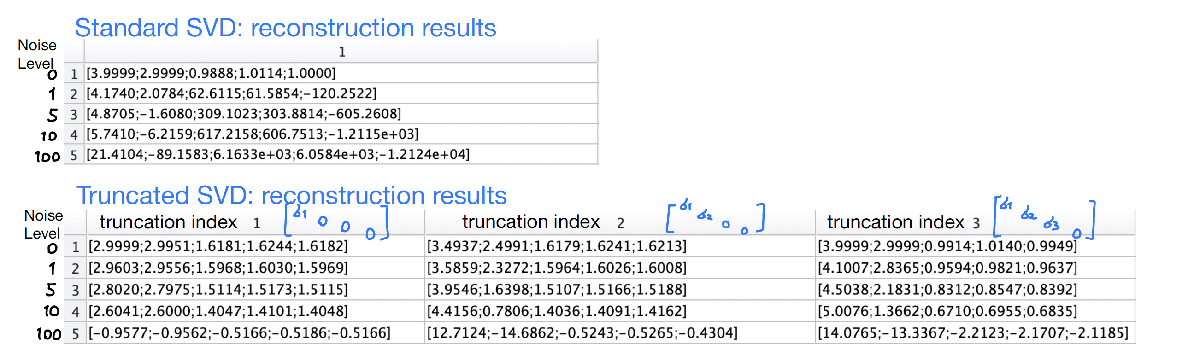

*Comments:*

*From the results we can see that:*

- *Truncated SVD can be beneficial to reconstructing a input signal from noisy measurements** (in a resonable range of noise level, cannot be too noisy). By using only the first few highest singular values, the rest lowest singular values are discarded which also corresponds to the noise. So that the **condition number can be decreased**. And this approach would also be much **quicker**.*

- *When the noise level is too high (e.g. amplification=100), both standard and truncated SVD failed.** They cannot reconstruct anything from such noisy measurements.*

**T3.4**: Compute the solution using Tikhonov regularization. Using L-curve, determine an optimal regularization parameter in range [1e-4; 1e-4*$2^{14}$] (simply double your regularization parameter every iteration). Show your L-curve, explain its meaning and how the optimal regularization parameter was selected. 	

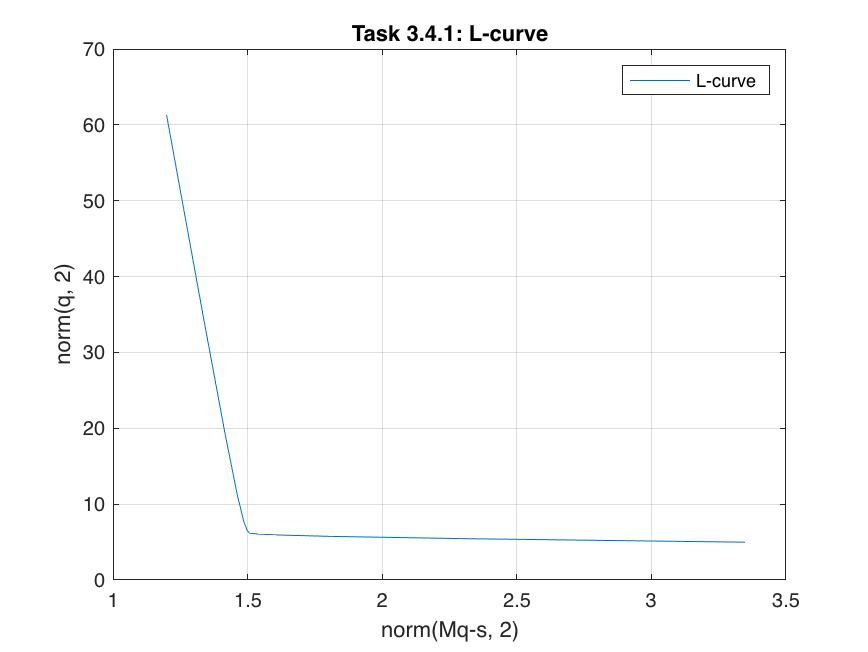

M = A;
noise_Tikhonov = .5 * randn(4, 1); 
s_Tikhonov = d + noise_Tikhonov;

lambda_range = 2.^(0:14) * 1e-4;
L = eye(5); % use identity linear operator L

% compute the approximate solutions q with different lambdas
q_values = arrayfun(@(lambda) (M.'*M + lambda*(L.'*L)) \ (M.'*s_Tikhonov), lambda_range, 'UniformOutput',false);
% compute x (norm of Mq-s) and y (norm of q) values for the L-curve
x_values = cellfun(@(q) norm(M*q-s_Tikhonov, 2), q_values);
y_values = cellfun(@(q) norm(q, 2), q_values);

figure(5); 
plot(x_values, y_values, 'DisplayName', 'L-curve'); 
hold on
xlabel('norm(Mq-s, 2)');
ylabel('norm(q, 2)');
title('Task 3.4.1: L-curve');
grid on
hold off
legend('Location', 'northeast')

*The L-curve shows how the reconstruction can be influenced by changing different lambda values. It is a good way to find an optimal value for lambda in Tikhonov regularization, by comparing the trade-off between:*

- *norm(Mq-s, 2) along x-axis: data term, how good the solution is to solve the original equation.*

- *norm(Lq, 2) along y-axis: regularization term, how good the solution can satisfy the 2nd-order condition.*

*And the optimal value for lambda is close to the corner of the L-curve, because it can:*

- *solve the equation,*

- *minimize functional,*

- *be most stable (with lowest condition number).*

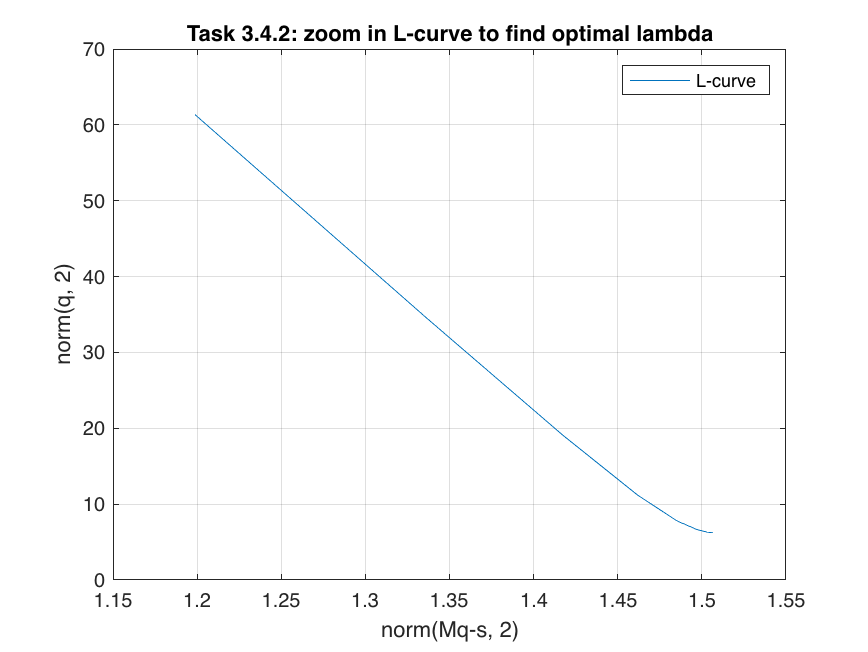

% search for the optimal value for lambda by finding the corner point
% here I zoom in the L-curve to only plot the first 8 data points
% so that it would be easier to determine the corner
figure(6); 
plot(x_values(1:8), y_values(1:8), 'DisplayName', 'L-curve'); 
hold on
xlabel('norm(Mq-s, 2)');
ylabel('norm(q, 2)');
title('Task 3.4.2: zoom in L-curve to find optimal lambda');
grid on
hold off
legend('Location', 'northeast')

*According to Figure 3.4.2, I would determine the corner point as x=0.0614781, y=5.39565. This corresponds to the lambda=0.0016.*

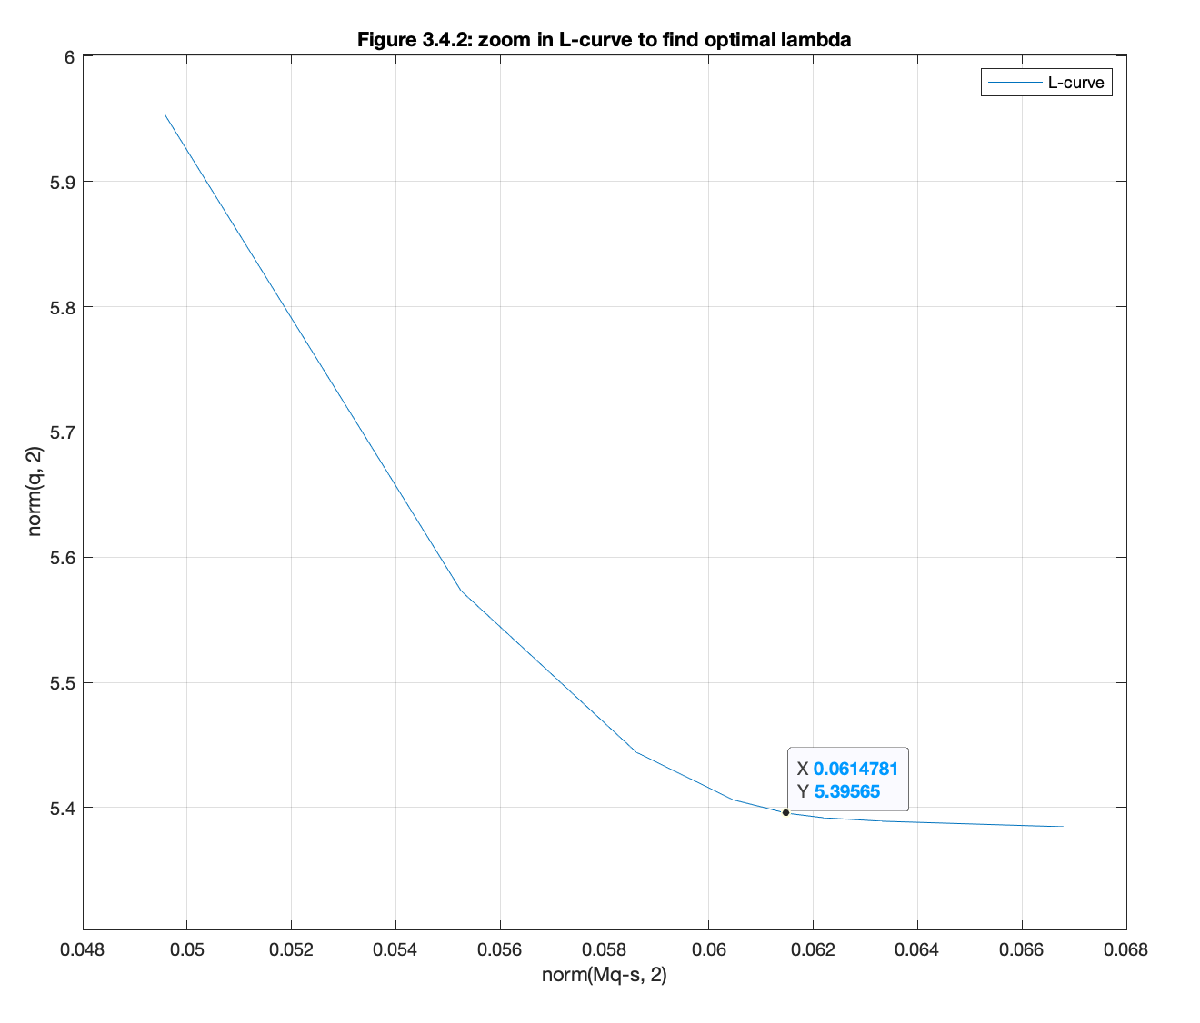

## Task 4. Newton's method

**T4.1**: Explain Newton’s method for finding minima of a function (algorithmic and geometric perspective);

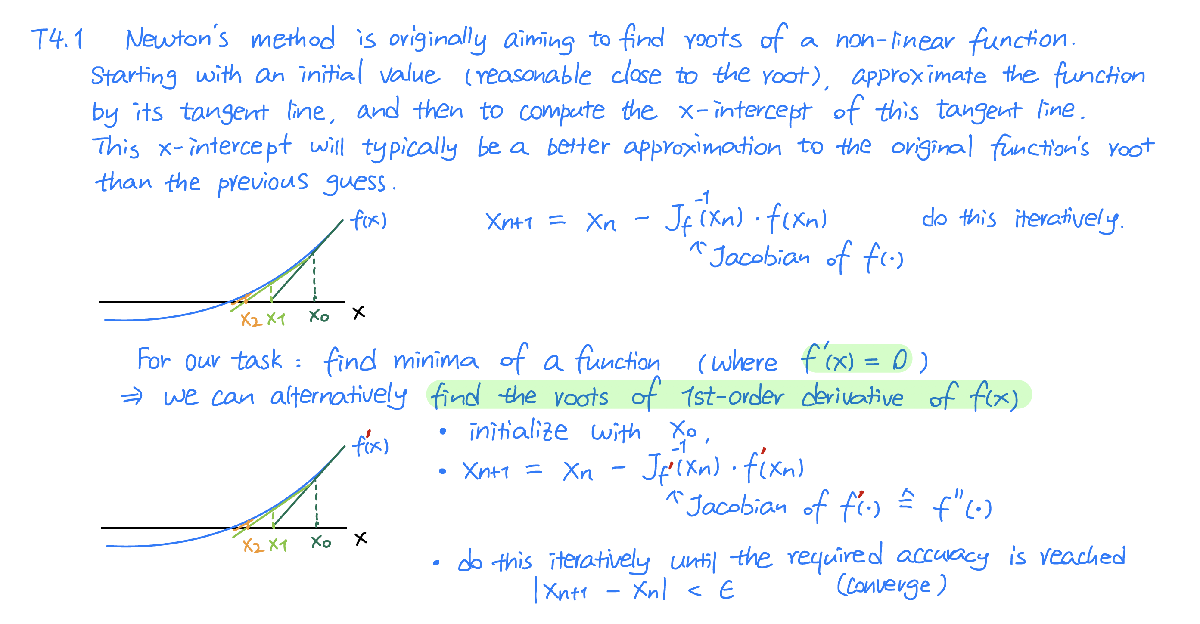

**T4.2**: Using Newton's method, find the minimizer of function$f\left(x\right)=\frac{x^2 }{2}-\sin \left(x\right),$ where the initial value is $x\left(0\right)=0\ldotp 5$. The required accuracy is $\varepsilon ={10}^{-5}$ , i.e. we stop when $\left|x^{\left(k+1\right)} -x^{\left(k\right)} \right|<\varepsilon$.	

% define parameters
epsilon = 10.^(-5);
x_init = 0.5;

syms f(x)
f(x) = 0.5*x.^2 - sin(x);
Df_1st_order = diff(f, x);
Df_2nd_order = diff(Df_1st_order, x);

% plot the 1st-order derivative of f(x) to visualize the desired minimizer
% (in this plot, we want to find the roots of f'(x) as minima)
x_newton = -1:0.01:2;
figure(7); 
plot(x_newton, Df_1st_order(x_newton), 'DisplayName', 'f''(x)'); 
hold on
xlabel('x');
ylabel('f''(x)');
title('Task 4.2: Plot of the 1st-order derivative of f(x)');
grid on
hold off
legend('Location', 'northwest')

% initialization
difference = 10; % set a random init value
num_ite = 0;
x_current = x_init;

% compute new x values iteratively until the required accuracy is reached
while difference >= epsilon
    x_next = x_current - double(Df_1st_order(x_current))./double(Df_2nd_order(x_current));
    difference = abs(x_next - x_current);
    num_ite = num_ite + 1;
    x_current = x_next;
    disp_message = ['Iteration number ', num2str(num_ite), ': x=', num2str(x_current), ...
        ' f''(x)=', num2str(double(Df_1st_order(x_current))), ...
        ', f(x)=', num2str(double(f(x_current)))];
    disp(disp_message)
end

Iteration number 1: x=0.75522 f'(x)=0.027103, f(x)=-0.40027
Iteration number 2: x=0.73914 f'(x)=9.4615e-05, f(x)=-0.40049
Iteration number 3: x=0.73909 f'(x)=1.181e-09, f(x)=-0.40049
Iteration number 4: x=0.73909 f'(x)=5.1276e-17, f(x)=-0.40049



disp('The minimizer is:')

The minimizer is:


x_current

x_current = 0.7391